# **demo19 of Im2mesh package**

demo19 - Function voxelMesh (voxel-based brick element)

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## voxelMesh

Function voxelMesh is used to generate voxel-based hexahedral mesh (with 8-node brick elements).

Let's start demo. First, we'll use function voxelMesh to generate mesh. In the next step, we'll export the mesh.

## Dependencies

No need to install any MATLAB toolboxes for this demo.

## Initialize

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size (optional).

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

## Import 3d image

Import 3d image using function importImSeqs or function importImStack.

### **Function importImSeqs**

If the 3d image is 2d image sequences in a folder, e.g. a001.tif, a002.tif, ..., we can use function importImSeqs to import them. 

folder_name = 'test_image_sequences';
im = importImSeqs( folder_name );

We use fucntion plotVolFaces to plot the volume faces of the imported 3d image.

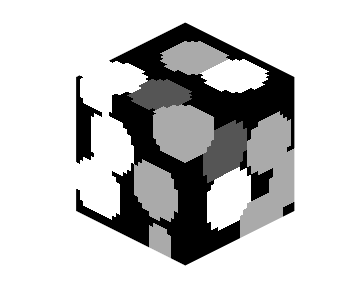

plotVolFaces( im );

### **Function importImStack**

If the 3d image is a 3d image stack cotaining all 2d image sequences, we can use function importImStack to import it. 

        file_name = 'test_stacked_image.tif';

        im = importImStack( file_name );

After importing, we can check the image size

size(im)

ans =     30    30    30


We can use the function 'unique' to list all the intensity in the image.

unique(im)

ans = 4×1 uint8 column vector
     0
    61
   134
   239


We can check the totoal number of intensity in the image.

length(unique(im))

ans = 4

We may perform multi-thresholding and image resizing before mesh generation.

**Image resizing is often necessary before generating mesh with voxel-based brick elements.** If the size of the input 3d image is large, the exported inp file and bdf file could be huge (>1 GB), which may cause trouble when importing inp or bdf file into finite element software. 

You could use Matlab built-in function imresize3 to resize 3d image.

## Generate mesh

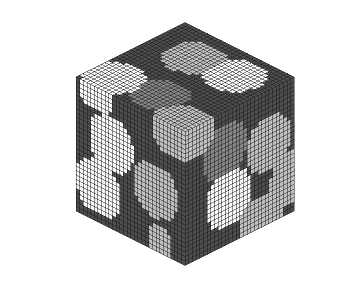

[ vert, ele, tnum, vert2, ele2 ] = voxelMesh( im );
plotMesh3d( vert, ele, tnum )

Note that function plotMesh3d could be very slow if the mesh data is large. I didn't optimize function plotMesh3d.

**Outputs of function voxelMesh**

vert is mesh nodes (for linear element)

ele is mesh elements (for linear element)

tnum is label of phase

vert2 is mesh nodes (for quadratic element)

ele2 is mesh elements (for quadratic element)

**More settings when plotting mesh**

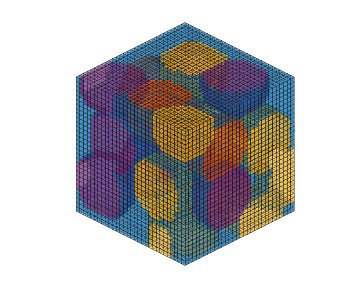

color_code = 1;
opt = [];
opt.faceAlpha = 0.5;
opt.edgeAlpha = 0.5;

plotMesh3d( vert, ele, tnum, color_code, opt );

## Export mesh

We have demonstrated how to do this in demo03

### Scale node coordinates

Set up scale.

% physical dimensions of a pixel in the image
dx = 1;

Scale node coordinates according to dx.

% scale node coordinates of linear elements
vert = vert * dx;

% scale node coordinates of quadratic elements
vert2 = vert2 * dx;

### Export as bdf file (Nastran bulk data)

precision = 8;
file_name = 'test_3d.bdf';

printBdf3d( vert, ele, tnum, [], precision, file_name );

printBdf3d Done! Check the bdf file!


### Export as inp file (Abaqus)

Please refer to the following link to learn more about exporting mesh: [https://github.com/mjx888/writeMesh/blob/main/README.md](https://github.com/mjx888/writeMesh/blob/main/README.md)

writeMesh [demo05](https://mjx888.github.io/writeMesh/demo05.html), [demo06](https://mjx888.github.io/writeMesh/demo06.html), and [demo09](https://mjx888.github.io/writeMesh/demo09.html) could be useful to you.

**Linear element**

ele_type = 'C3D8';
precision = 8;
file_name = 'test_linear.inp';

opt = [];   % reset
opt.tf_printMaxMinNode = 0;
opt.tf_printInterfNode = 0;

printInp3d( vert, ele, tnum, ele_type, precision, file_name, opt );

printInp3d Done! Check the inp file!


**Quadratic element**

ele_type = 'C3D20';
precision = 8;
file_name = 'test_quadratic.inp';

opt = [];   % reset
opt.tf_printMaxMinNode = 0;
opt.tf_printInterfNode = 0;

printInp3d( vert2, ele2, tnum, ele_type, precision, file_name, opt );

printInp3d Done! Check the inp file!


## Phase selection before meshing

We can specify phase selection before meshing. See demo08 for example.

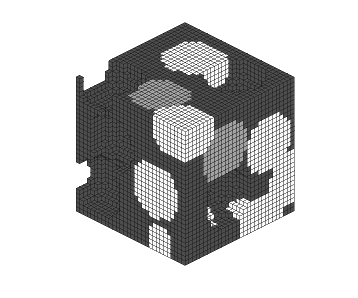

opt = [];   % reset
opt.select_phase = [1 2 3];
[ vert, ele, tnum, vert2, ele2 ] = voxelMesh( im, opt );

plotMesh3d( vert, ele, tnum )

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo